# Polinomios de interpolación en el análisis de temperatura

TNov = readmatrix('noviembre.csv','Range','C12:C730')';
tNov = (0:1:length(TNov)-1); 

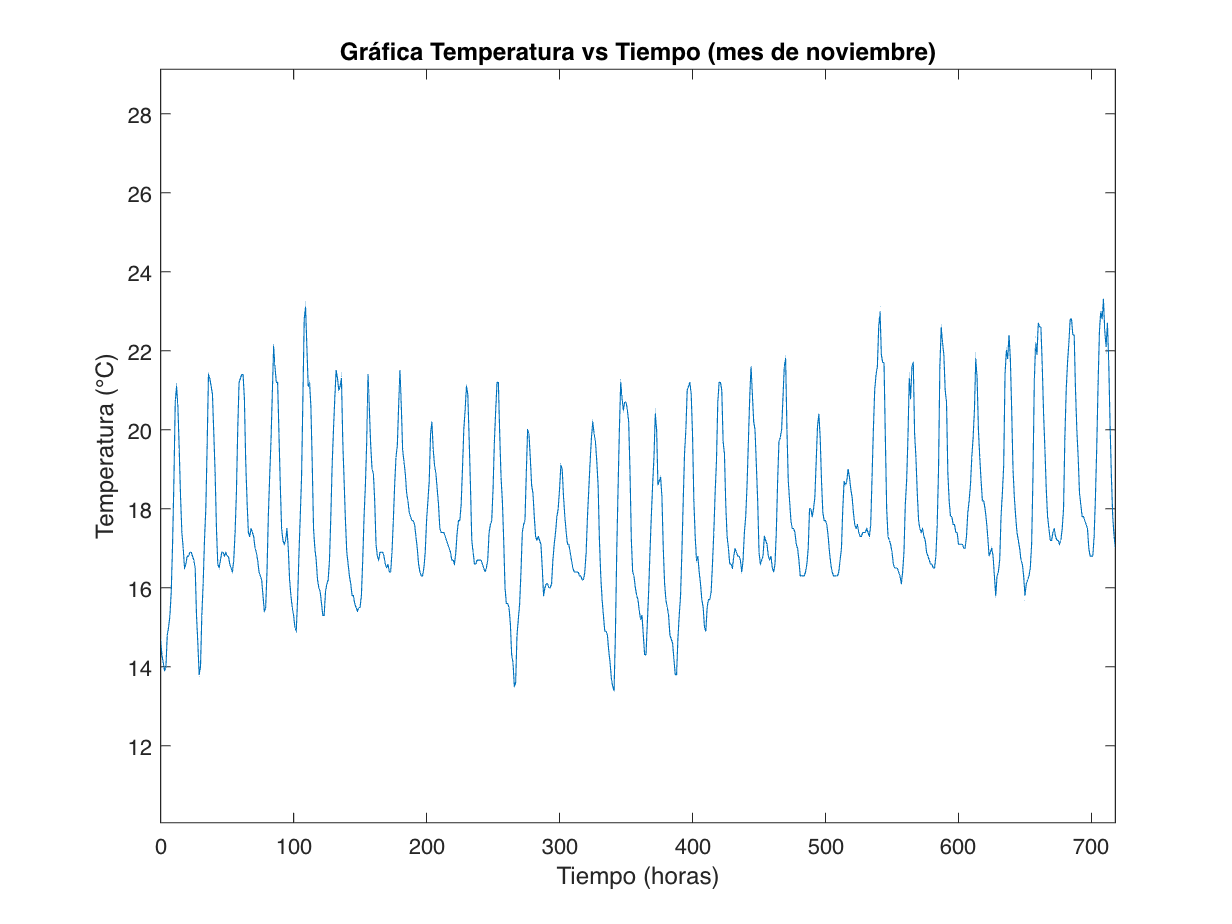

GraficaGeneral(TNov, tNov); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 4;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

Hora por defecto: 12


Grado de polinomio de mínimos cuadrados por defecto: 4


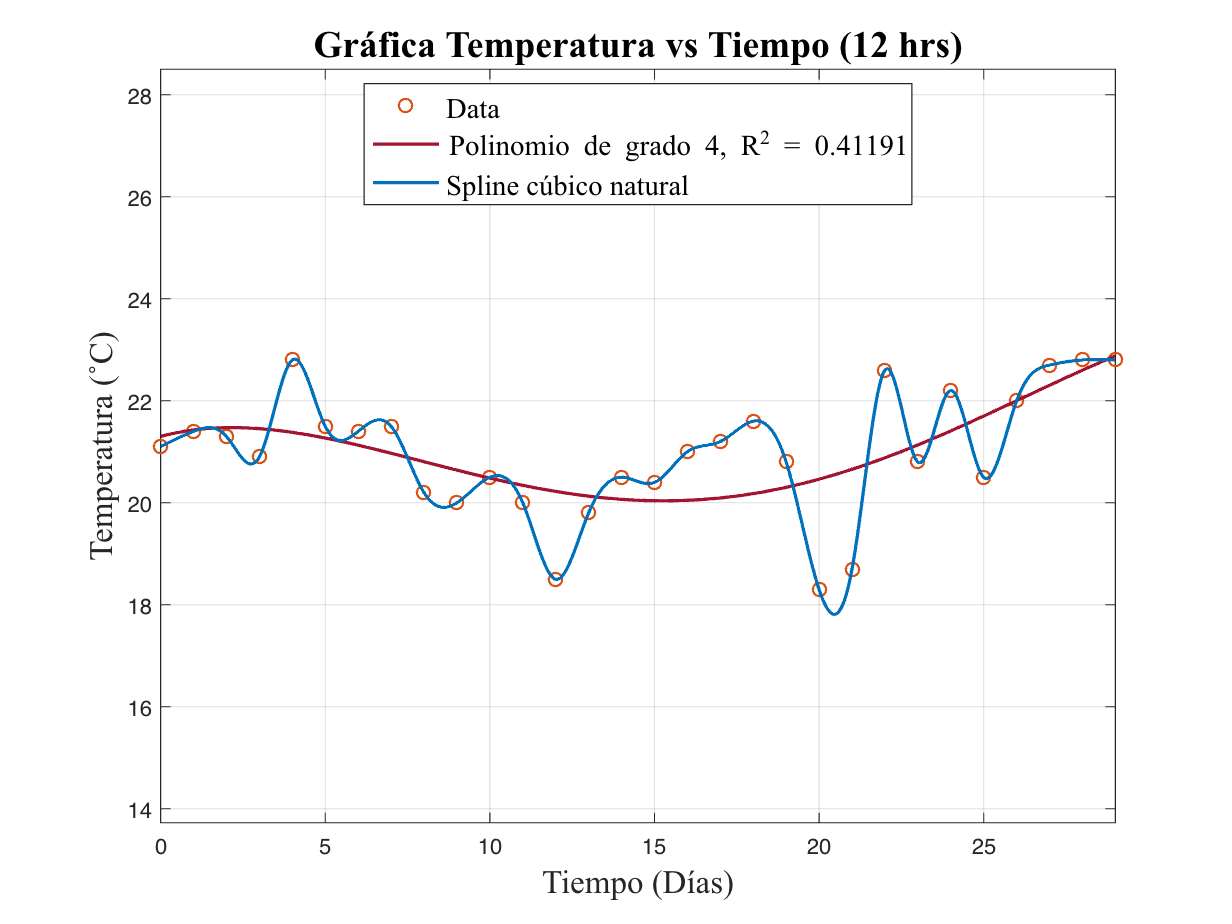

[tNovHora, TNovHora, Sx, P] = GraficaSpline(TNov, hora+1, grado);
hold off

### 
$$\mathrm{Polinomio}\;\mathrm{de}\;\mathrm{Mínimos}\;\mathrm{Cuadrados}:$$



$$P_4 \left(t\right)=\;$$


syms t

disp(poly2sym(round(vpa(P, 2), 8), t))

$$-0.0000382\,t^{4}+0.00260779\,t^{3}-0.04751014\,t^{2}+0.17076797\,t+21.3012758$$

### 
$$\mathrm{Spline}\;\mathrm{Cúbico}\;\mathrm{Natural}:$$


#### 
$$S_i \left(t\right)={a\left(t-t_i \right)}^3 +{b\left(t-t_i \right)}^2 +c\left(t-t_i \right)+d\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

    i     (t-t[i])        a             b            c         d       [t(i), t(i+1)]  
    __    ________    __________    _________    _________    ____    _________________

     0    "(t-0)"      -0.023477            0      0.32348    21.1    "si t ∈ [0, 1]"  
     1    "(t-1)"       -0.28262    -0.070431      0.25305    21.4    "si t ∈ [1, 2]"  
     2    "(t-2)"         1.2539     -0.91828     -0.73566    21.3    "si t ∈ [2, 3]"  
     3    "(t-3)"        -2.1331       2.8435       1.1896    20.9    "si t ∈ [3, 4]"  
     4    "(t-4)"         1.7786      -3.5559      0.47726    22.8    "si t ∈ [4, 5]"  
     5    "(t-5)"       -0.58139         1.78      -1.2986    21.5    "si t ∈ [5, 6]"  
     6    "(t-6)"       -0.45309     0.035849      0.5172

Graficamos el polinomio interpolante de Newton:

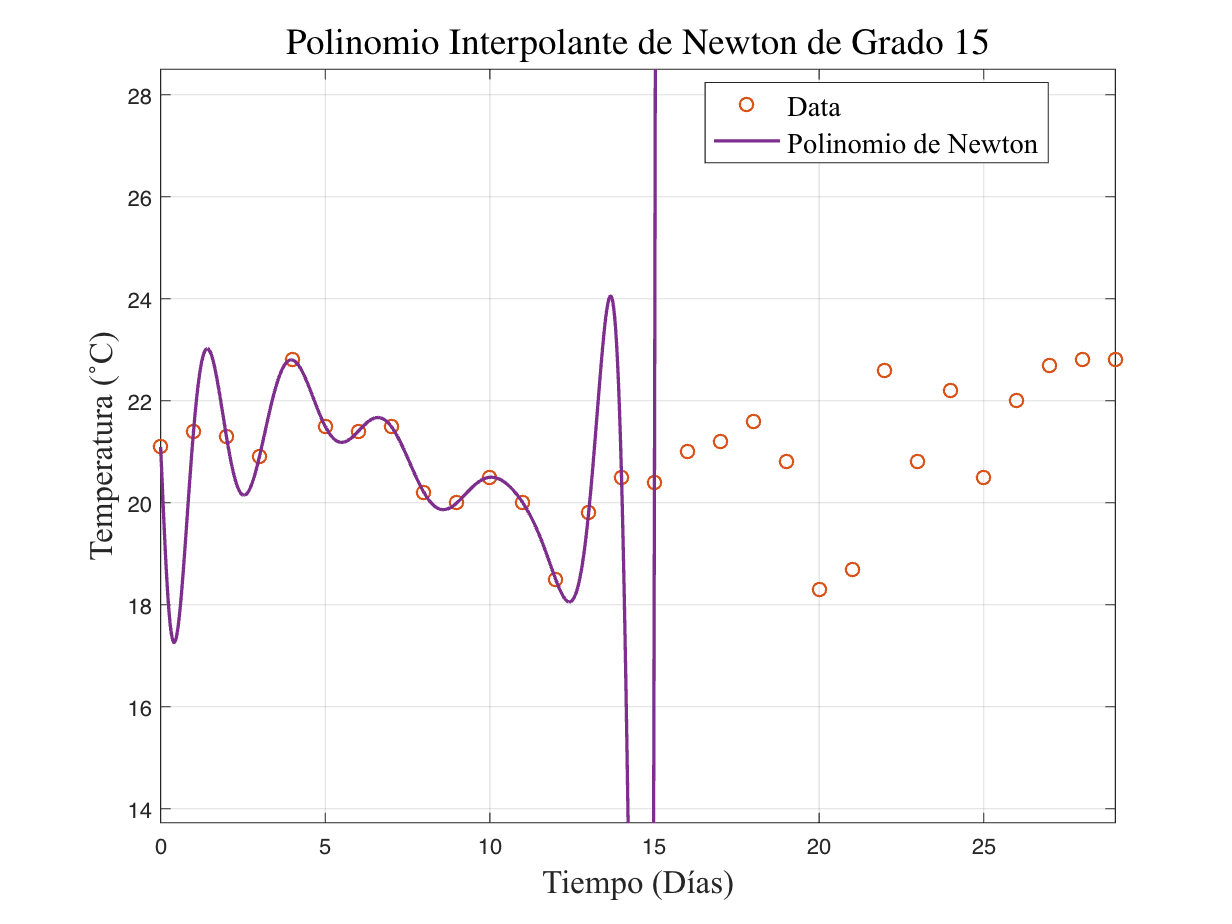

GraficaNewton(tNovHora, TNovHora, ceil(length(tNovHora)/2));

Gráfica de aproximación de Temperatura para los primeros días de diciembre:

TDic = readmatrix('diciembre.csv','Range','C12:C263')';
TDicHora = TDic((hora+1):24:end);
[~, n] = size(TDicHora);

fprintf("Cantidad de Temperaturas reales de diciembre disponibles: %d", n)

Cantidad de Temperaturas reales de diciembre disponibles: 10

while true
    cant_dias = input("Ingrese la cantidad [c] de días de diciembre para estimar (c<=" +int2str(n) + "): ");
    if cant_dias <= n
        break
    end
end

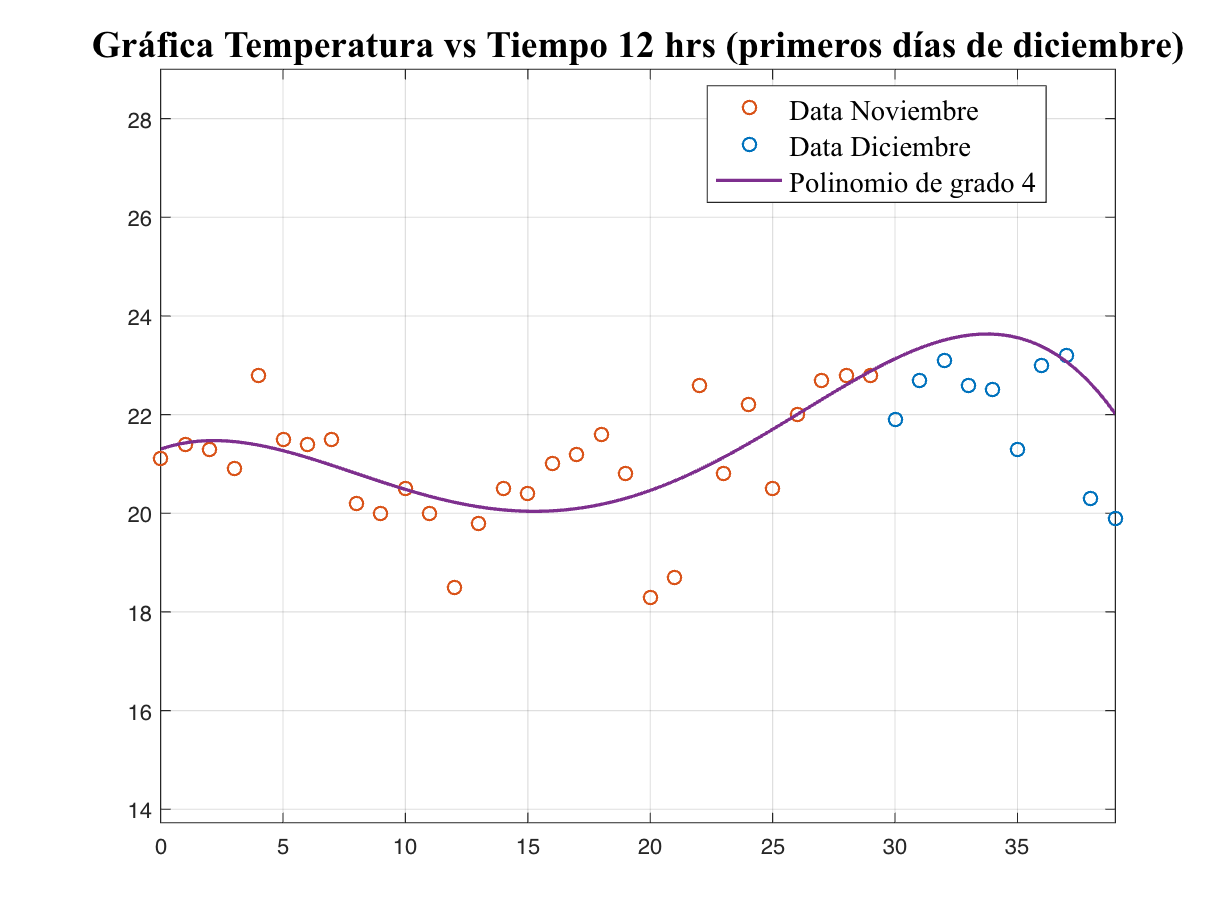

GraficaConDiciembre(TNovHora, TDicHora(1, 1:cant_dias), hora+1, P, grado, cant_dias);

Taprox = polyval(P, (30:1:(29+cant_dias)));
Treal = TDicHora(1:cant_dias);
Error_absoluto = abs(Treal - Taprox);
disp("Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_absoluto);

Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario
    1.2322    0.6465    0.4102    1.0101    1.1321    2.2609    0.3808    0.1253    2.3249    2.1127



fprintf("Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: %f", norm(Error_absoluto, 2))

Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: 4.421286

Error_relativo = Error_absoluto./Treal;
disp("Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_relativo);

Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0563    0.0285    0.0178    0.0447    0.0503    0.1061    0.0166    0.0054    0.1145    0.1062



fprintf("Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: %f", norm(Error_relativo, 2))

Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: 0.211612